# Práctica 1. Modelo de movimiento

En esta práctica vamos a implementar el modelo de movimiento basado en odometría mediante la técnica de sampling. Comenzaremos implementando funciones básicas que utilizaremos a lo largo de la práctica.

## 1 Composición de poses

Implementa una función que realice la composición de dos poses, es decir que dadas 𝑝𝑝1 = [𝑥𝑥1 𝑦𝑦1 𝜃𝜃1]𝑇𝑇 y 𝑝𝑝2 = [𝑥𝑥2 𝑦𝑦2 𝜃𝜃2]𝑇𝑇, devuelva el resultado de la operación 𝑝𝑝1 ⊕ 𝑝𝑝2

pose_comp([-2.5 0 pi/2]', [0.2 0 -10*pi/180]')

ans =    -2.5000
    0.2000
    1.3963


## 2 Modelo de odometría

Diseña un programa que iterativamente comande un robot para seguir una trayectoria en forma de cuadrado de lado 10 metros. Para ello necesitarás hacer uso de la composición de poses para calcular en cada iteración 𝑥𝑡 = 𝑥𝑡−1 ⊕ 𝑢𝑡, siendo 𝑢𝑡 = (Δ𝑥 Δy Δ𝜃)𝑇. Considera que en cada paso el robot puede avanzar 1 metro o girar 90⁰. 

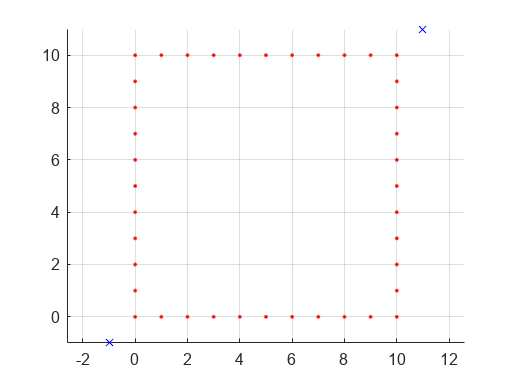

cuadrado(10);

## 3 Comandando mediante velocidad lineal y angular

Repite el ejercicio anterior (cuadrado de lado 10 metros), pero utilizando en este caso una acción de control 𝑢𝑡 = (Vp W)𝑇 formada por una velocidad lineal y otra angular. 

Asume que dichos comandos de velocidad se aplican al robot cada 0.5s. Los comandos se calculan de las siguientes ecuaciones:

        x(Δt) = ∫vP (t) cos(wt)dt

        y(Δt) = ∫vP (t) sin(wt)dt

        θ (Δt) = ∫ w(t) dt

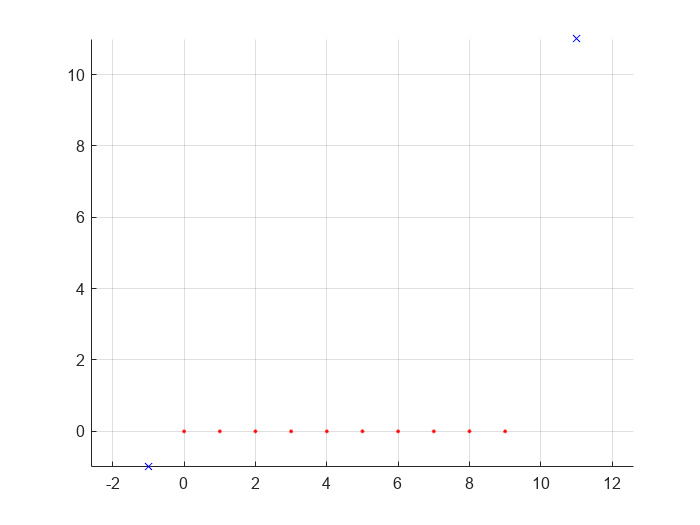

cuadrado_velocidades(10);

## 4 Añadiendo ruido

Modifica el ejercicio 2 para que la acción de control se vea afectada por ruido. Dibuja la trayectoria del robot con y sin ruido y comprueba cómo varía para diferentes valores de sigma

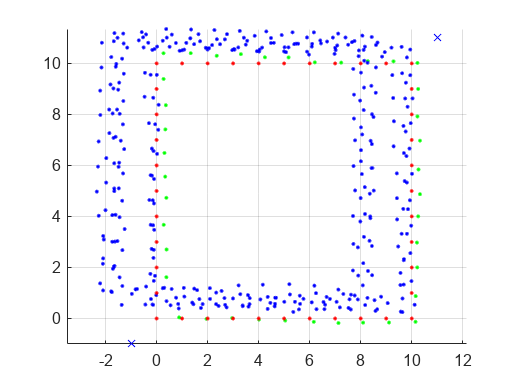

cuadrado_ruido(10)

## 5 Usando partículas

Vamos a estimar la posición del robot en base a partículas, “samples” de poses probables en las que se puede encontrar el vehículo, atendiendo a la naturaleza probabilística del ruido que estamos considerando. Para ello repite el ejercicio 4, mostrando la posición sin ruido (odometría) del robot, junto a 100 partículas que indican posibles posiciones del robot (en base a otras tantas acciones de control ruidosas).

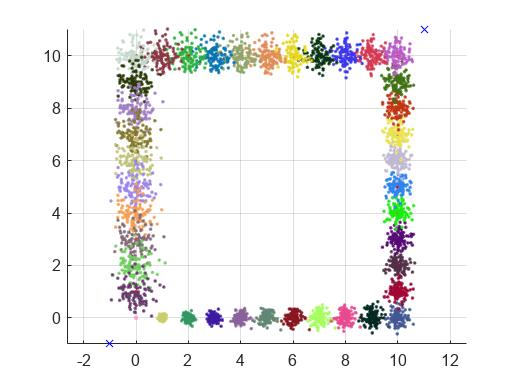

cuadrado_particulas(10)